b = 1.02;
c = 0.08;
h = 0.8603;
lambda = pi/10;
V = 3; % let's only reduce the speed
a = 0.347;
g = 9.81;
m = 84;

k1 = b^2/((V^2*sin(lambda) - b*g*cos(lambda))*m*a*c*sin(lambda));
k2 = b*g/(V^2*sin(lambda) - b*g*cos(lambda));

% k1 = 5;
% k2 = 1;

sys_tf_uns = get_bicycle_fb_tf(h, V, a,b,k1,k2,c,lambda);
sys_tf_uns

sys_tf_uns =
 
   -0.07859 s - 0.6555
  ----------------------
  s^2 - 0.5446 s - 15.95
 
Continuous-time transfer function.



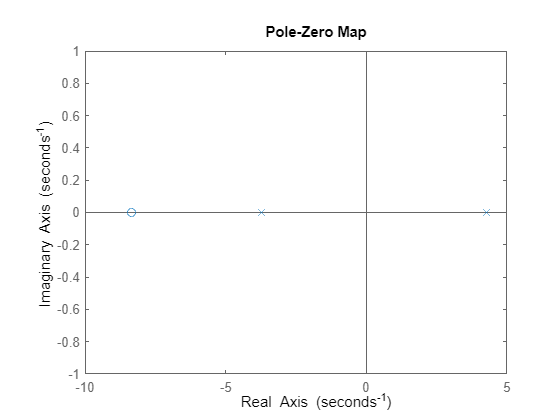

pzmap(sys_tf_uns)

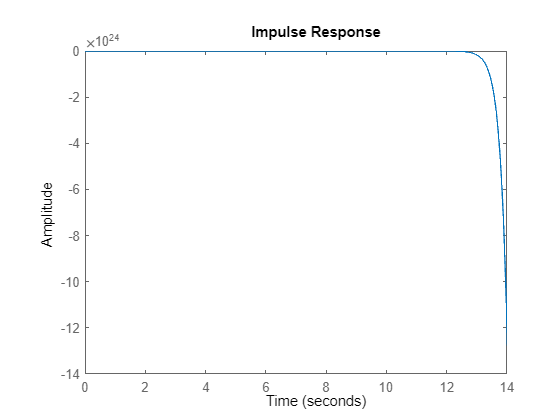

impulse(sys_tf_uns)

**state space**

% ccf
A = [
    0                                                       1;
    g/h-k2*(V^2*h-a*c*g)*sin(lambda)/(b*h^2)    -a*V*sin(lambda)/(b*h)*k2
];
B = [
    0;
    1
];

C = [(V^2*h-a*c*g)*sin(lambda)/(b*h^2)*k1 a*V*sin(lambda)/(b*h)*k1];
D = 0;


sys_ss = ss(A,B,C,D)

sys_ss =
 
  A = 
           x1      x2
   x1       0       1
   x2   15.95  0.5446
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
             x1        x2
   y1   -0.6555  -0.07859
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



**Stability Analysis**

Q = eye(length(A));
P = lyap(A,Q);

if all(eig(P) > 0)
    disp('The system is stable.')
else
    disp('The system is not stable.')
end

The system is not stable.


**Designing Controller (pole placement) and Observer**

pole(sys_tf_uns)

ans =     4.2748
   -3.7302


% desired_poles = [-6.6567+12.6826i  -6.6567-12.6826i]
desired_poles = [-6.6567,-6.6567]

desired_poles =    -6.6567   -6.6567


K = acker(A,B,[-6.6567,-6.6567])

K =    60.2576   13.8580


A_pp = A-B*K;
B_pp = B;
C_pp = C;
D_pp = D;

sys_ss_pp = ss(A_pp, B_pp, C_pp, D_pp);
sys_ss_pp

sys_ss_pp =
 
  A = 
           x1      x2
   x1       0       1
   x2  -44.31  -13.31
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
             x1        x2
   y1   -0.6555  -0.07859
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



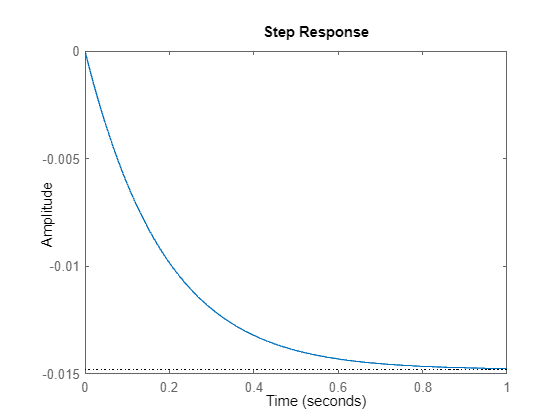

step(sys_ss_pp)

eig(A_pp)

ans =    -6.6567
   -6.6567


[pp_num, pp_denum] = ss2tf(A_pp, B_pp, C_pp, D_pp);
sys_tf_pp = tf(pp_num, pp_denum);
sys_tf_pp 

sys_tf_pp =
 
   -0.07859 s - 0.6555
  ---------------------
  s^2 + 13.31 s + 44.31
 
Continuous-time transfer function.



pole(sys_tf_pp)

ans =    -6.6567
   -6.6567


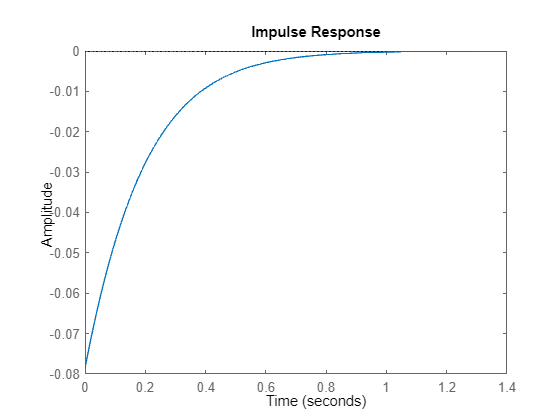

impulse(sys_tf_pp);

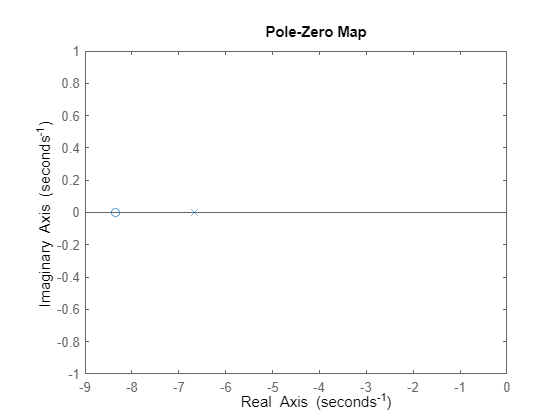

pzmap(sys_tf_pp);

**LQR controller**

tmp = size(B);
n_inputs = tmp(2);
Q = 10*eye(length(A))

Q =     10     0
     0    10


R = 5*eye(n_inputs)

R = 5

[K_lqr,S,P] = lqr(sys_ss,Q,R)

K_lqr =    31.9545    8.6813


S =   607.8584  159.7723
  159.7723   43.4065


P =    -3.3315
   -4.8051


sys_ss_lqr = ss(A-B*K_lqr, B,C,D)

sys_ss_lqr =
 
  A = 
           x1      x2
   x1       0       1
   x2  -16.01  -8.137
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
             x1        x2
   y1   -0.6555  -0.07859
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



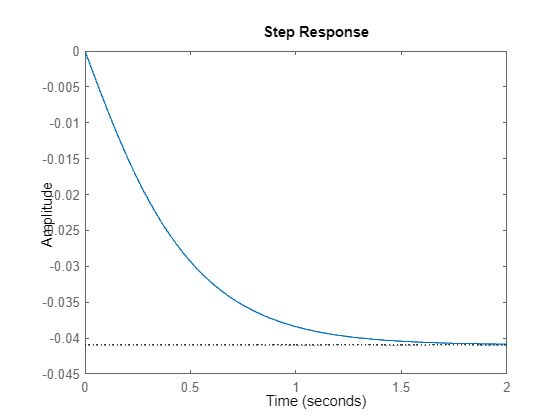

step(sys_ss_lqr)

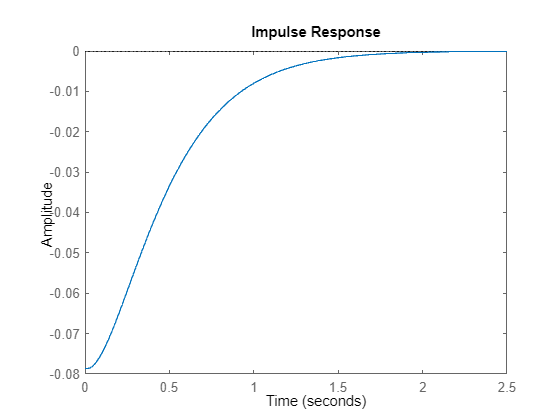

impulse(sys_ss_lqr)

**let's test LQR on the OCF form too**

% ocf
A_ocf = [
    -a*V*sin(lambda)/(b*h)*k2                       1;
    g/h-k2*(V^2*h-a*c*g)*sin(lambda)/(b*h^2)      0
];
B_ocf = [
    a*V*sin(lambda)/(b*h)*k1;
    (V^2*h-a*c*g)*sin(lambda)/(b*h^2)*k1
];

C_ocf = [1  0];
D_ocf = 0;


sys_ss_ocf = ss(A_ocf,B_ocf,C_ocf,D_ocf)

sys_ss_ocf =
 
  A = 
           x1      x2
   x1  0.5446       1
   x2   15.95       0
 
  B = 
             u1
   x1  -0.07859
   x2   -0.6555
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



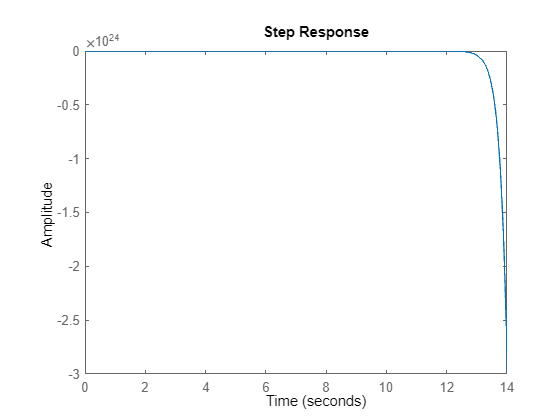

step(sys_ss_ocf)

impulse(sys_ss_ocf)

tmp = size(B);
n_inputs = tmp(2);

% tuning using Bryson's rule
Q = [
    1/(0.1)^2  0;
    0   0
]

Q =   100.0000         0
         0         0


% tuning using Bryson's rule
R = 1*eye(n_inputs)

R = 1


[K_lqr,S,P] = lqr(sys_ss_ocf,Q,R)

K_lqr =   -38.7318   -8.7011


S =   177.0979   37.8545
   37.8545    8.7354


P =   -4.1014 + 0.6472i
  -4.1014 - 0.6472i



sys_ss_lqr = ss(A_ocf-B_ocf*K_lqr, B_ocf,C_ocf,D_ocf)

sys_ss_lqr =
 
  A = 
           x1      x2
   x1  -2.499  0.3162
   x2  -9.444  -5.704
 
  B = 
             u1
   x1  -0.07859
   x2   -0.6555
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



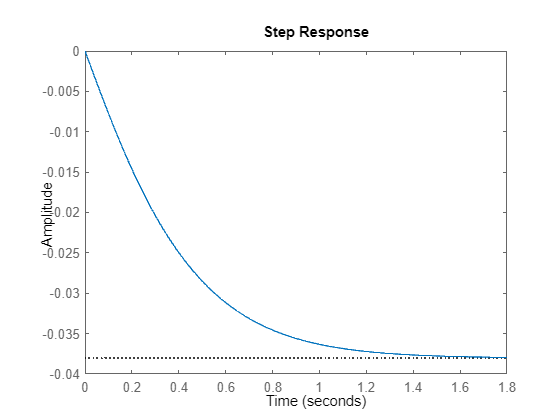

step(sys_ss_lqr)

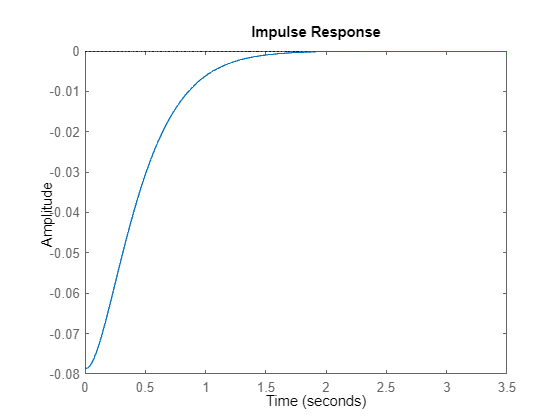

impulse(sys_ss_lqr)